close all
clc
clear all

## Basic Config

wirediameter = 12e-3;        % (m)
c = physconst('lightspeed'); % (m)

fc = 300e6;                  % Center frequency (Hz)
lambda = c / fc;             % Wavelength (m)


## Exciter

d = dipole

d =   dipole with properties:

        Length: 2
         Width: 0.1000
    FeedOffset: 0
          Tilt: 0
      TiltAxis: [1 0 0]
          Load: [1×1 lumpedElement]


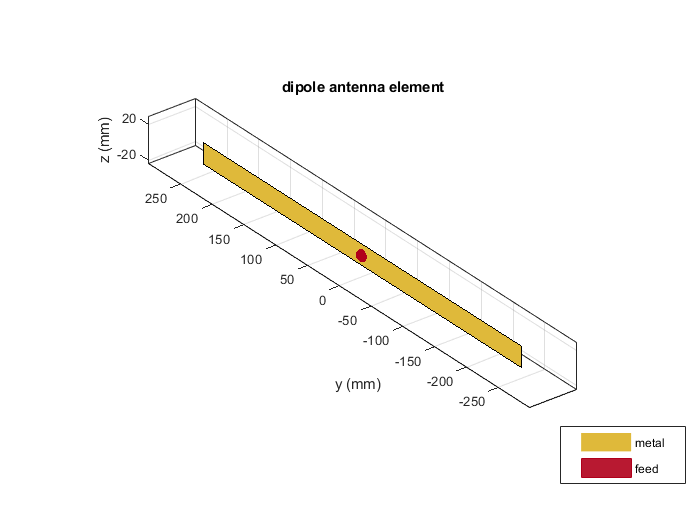

d.Length = 0.5 * lambda;
d.Width = cylinder2strip(wirediameter / 2);
d.Tilt = 90;
d.TiltAxis = [1 0 0];
show(d)

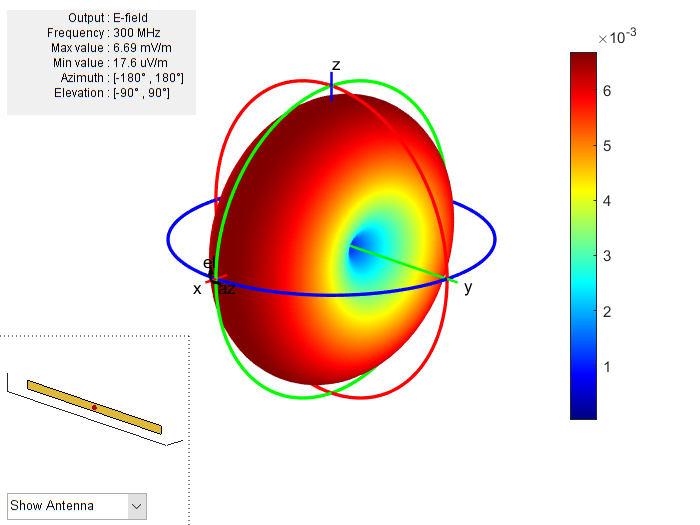

pattern(d, fc, 'Type', 'efield')

## Plane Reflector

rc = reflector

rc =   reflector with properties:

              Exciter: [1×1 dipole]
            Substrate: [1×1 dielectric]
    GroundPlaneLength: 0.2000
     GroundPlaneWidth: 0.2000
              Spacing: 0.0750
      EnableProbeFeed: 0
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]


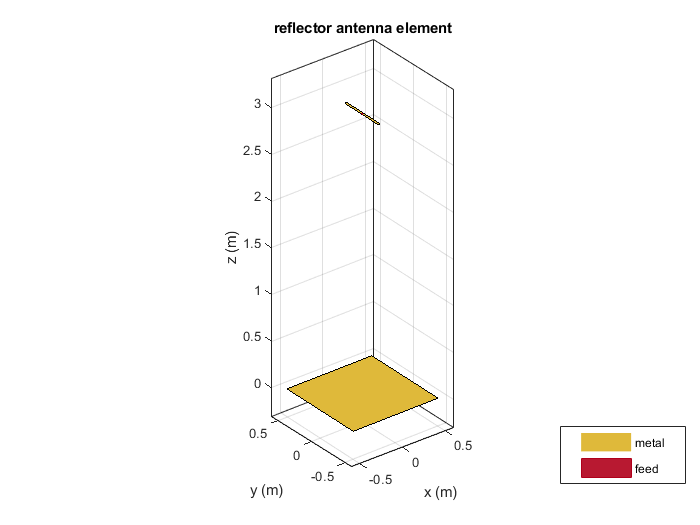


rc.Exciter = d;
rc.GroundPlaneLength = 1 * lambda;
rc.GroundPlaneWidth = 1 * lambda;
rc.Spacing = 3 * lambda;
rc.Tilt = 0;
rc.TiltAxis = [1 0 0];
show(rc)

% view(0, 0)

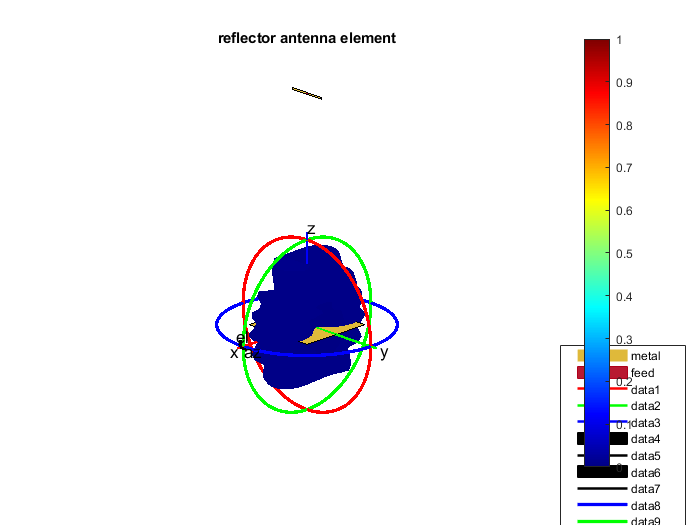

% Radiation Pattern Plot

[efield, az, el] = pattern(rc, fc, 'Type', 'efield');
phi = az';
theta = (90-el);
MagE = efield';
patternCustom(MagE, theta, phi)

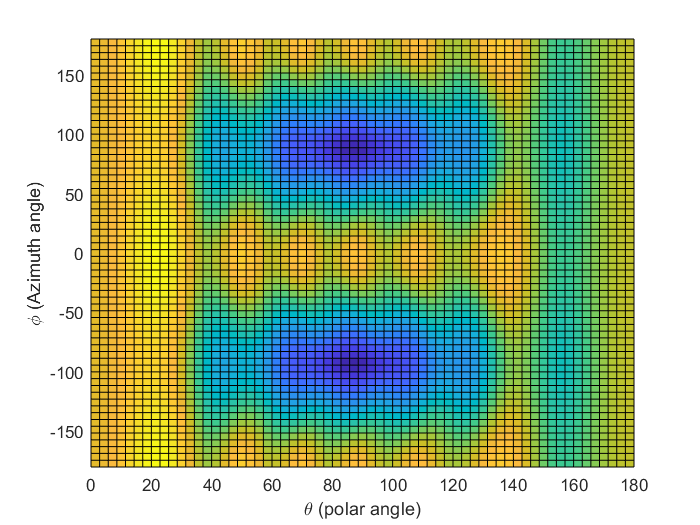


% Resize MagE(73, 37) to MagE_(64, 64)
out_size = [64, 64];
MagE_ = imresize(MagE, out_size);

% Plot MagE_
[X_, Y_] = meshgrid(linspace(180, 0, out_size(1)), ...
                    linspace(180, -180, out_size(2)));

surf(X_, Y_, MagE_);
xlabel('\theta (polar angle)');
ylabel('\phi (Azimuth angle)');
axis([0, 180, -180, 180]);
view(2)

drawnow
    
% % E-plane
% figure;
% patternElevation(rc, fc, 0, 'Elevation', 0:1:359);
% pE = polarpattern('gco');
% 
% % H-plane
% figure;
% patternElevation(rc, fc, 90, 'Elevation', 0:1:359);
% pH = polarpattern('gco');

## Corner Reflector

rc = reflectorCorner

rc =   reflectorCorner with properties:

              Exciter: [1×1 dipole]
    GroundPlaneLength: 0.2000
     GroundPlaneWidth: 0.4000
          CornerAngle: 90
              Spacing: 0.0750
                 Tilt: 0
             TiltAxis: [1 0 0]
                 Load: [1×1 lumpedElement]


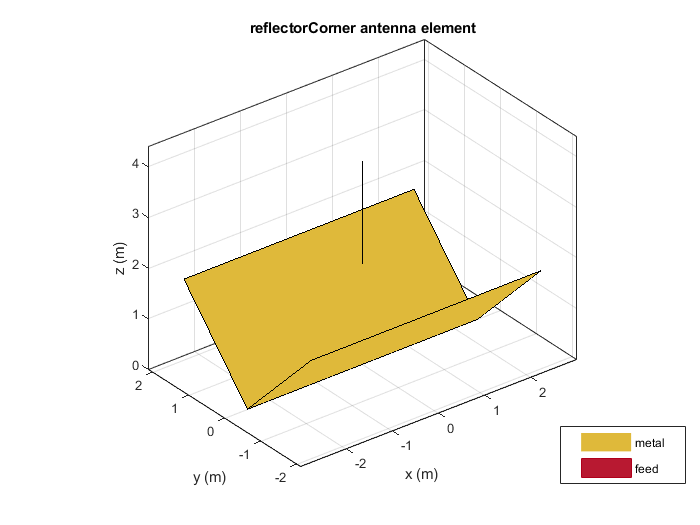


rc.Exciter = d;
rc.GroundPlaneLength = 5 * lambda;
rc.GroundPlaneWidth = 5 * lambda;
rc.Spacing = 3 * lambda;
show(rc)

% view(0, 0)

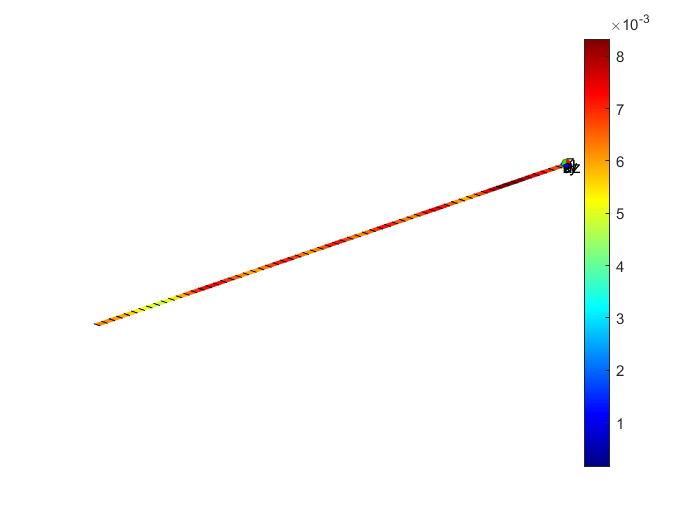

% Radiation Pattern Plot

[efield, az, el] = pattern(rc, fc, 'Type', 'efield');
phi = az';
theta = (90-el);
MagE = efield';
patternCustom(MagE, theta, phi)

## Circular Reflector

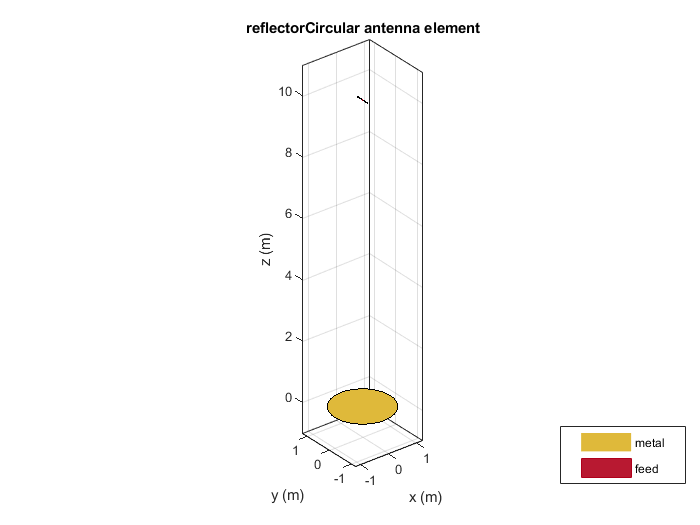

rc = reflectorCircular;
rc.Exciter = d;
rc.GroundPlaneRadius= 1 * lambda;
rc.Spacing = 10 * lambda;
rc.Tilt = 0;
rc.TiltAxis = [1 0 0];
show(rc)

% view(0, 0)

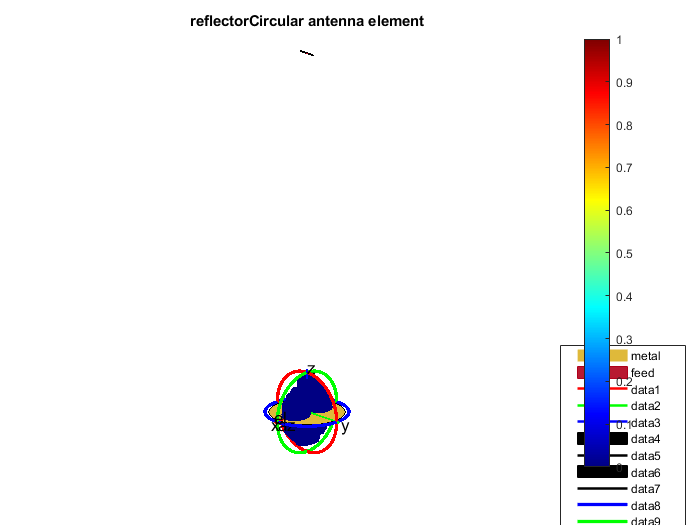

% Radiation Pattern Plot

[efield, az, el] = pattern(rc, fc, 'Type', 'efield');
phi = az';
theta = (90-el);
MagE = efield';
patternCustom(MagE, theta, phi)

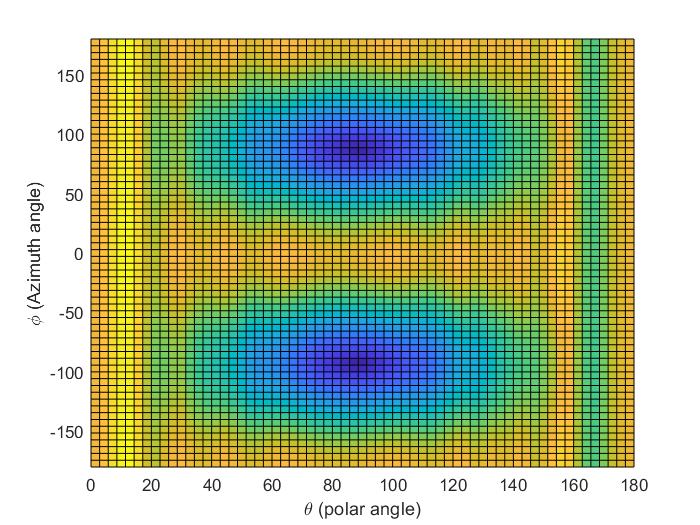


% Resize MagE(73, 37) to MagE_(64, 64)
out_size = [64, 64];
MagE_ = imresize(MagE, out_size);

% Plot MagE_
[X_, Y_] = meshgrid(linspace(180, 0, out_size(1)), ...
                    linspace(180, -180, out_size(2)));

surf(X_, Y_, MagE_);
xlabel('\theta (polar angle)');
ylabel('\phi (Azimuth angle)');
axis([0, 180, -180, 180]);
view(2)

drawnow
    
% % E-plane
% figure;
% patternElevation(rc, fc, 0, 'Elevation', 0:1:359);
% pE = polarpattern('gco');
% 
% % H-plane
% figure;
% patternElevation(rc, fc, 90, 'Elevation', 0:1:359);
% pH = polarpattern('gco');

## Parabolic Reflector

rc = reflectorParabolic

rc =   reflectorParabolic with properties:

        Exciter: [1×1 dipole]
         Radius: 0.1500
    FocalLength: 0.0750
     FeedOffset: [0 0 0]
           Tilt: 0
       TiltAxis: [1 0 0]
           Load: [1×1 lumpedElement]


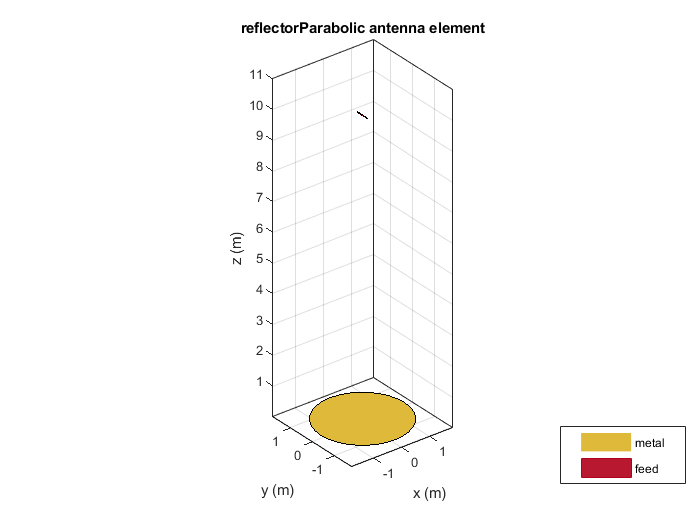

rc.Exciter = d;
rc.Radius = 1.5 * lambda;
rc.FocalLength = 5 * lambda;
rc.FeedOffset = [0 0 5];
rc.Tilt = 0;
rc.TiltAxis = [1 0 0];
show(rc)

% view(0, 0)

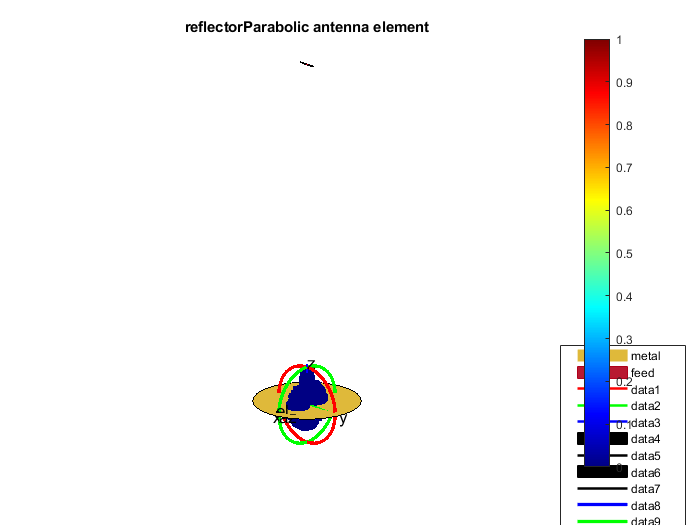

% Radiation Pattern Plot

[efield, az, el] = pattern(rc, fc, 'Type', 'efield');
phi = az';
theta = (90-el);
MagE = efield';
patternCustom(MagE, theta, phi)

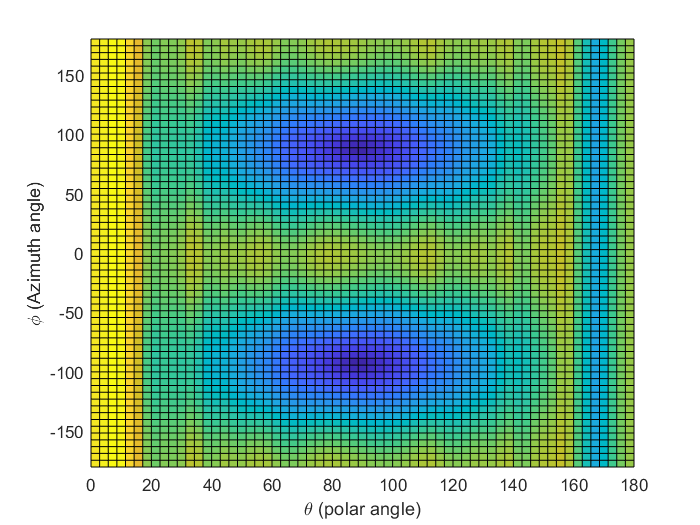


% Resize MagE(73, 37) to MagE_(64, 64)
out_size = [64, 64];
MagE_ = imresize(MagE, out_size);

% Plot MagE_
[X_, Y_] = meshgrid(linspace(180, 0, out_size(1)), ...
                    linspace(180, -180, out_size(2)));

surf(X_, Y_, MagE_);
xlabel('\theta (polar angle)');
ylabel('\phi (Azimuth angle)');
axis([0, 180, -180, 180]);
view(2)

drawnow
    
% % E-plane
% figure;
% patternElevation(rc, fc, 0, 'Elevation', 0:1:359);
% pE = polarpattern('gco');
% 
% % H-plane
% figure;
% patternElevation(rc, fc, 90, 'Elevation', 0:1:359);
% pH = polarpattern('gco');